依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

模板阶段相关性

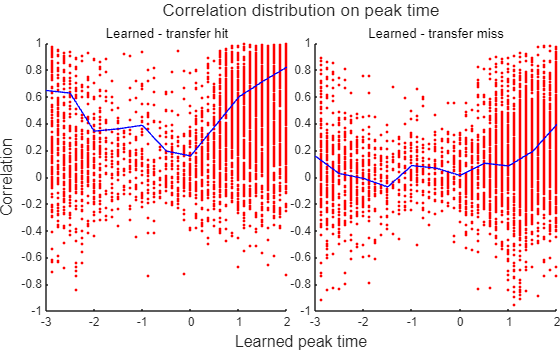

Impl('光声迁移命中错失');

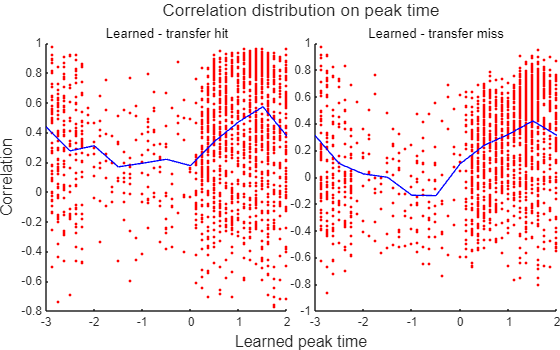

Impl('声光迁移命中错失');

function Impl(SheetName)
import TransferLearning.*
Data=NtatsFromSheetname(SheetName,Flags.Different_cells_stripped).NTATS{:,:,["Learned","Transfer_hit","Transfer_miss"]};
Data=pagetranspose(Data(any(Data,2:3),:,:));
[~,PeakTimeIndex]=max(Data(:,:,1),[],1);
PeakTime=PeakTimeIndex/8-3;
PeakTimeIndex=uint8(PeakTimeIndex/4)+1;
NumPTI=max(PeakTimeIndex);
Colors=GlobalOptimization.ColorAllocate(2,[1,1,1;1,1,1]);
figure;
Layout=tiledlayout('flow',TileSpacing='tight',Padding='none');
nexttile;
scatter(PeakTime,diag(corr(Data(:,:,1),Data(:,:,2))),'.',MarkerEdgeColor=Colors(1,:));
line(linspace(-3,2,NumPTI),splitapply(@(D1,D2)corr(D1(:),D2(:)),Data(:,:,1),Data(:,:,2),PeakTimeIndex),Color=Colors(2,:),LineWidth=1);
title('Learned - transfer hit');
nexttile;
scatter(PeakTime,diag(corr(Data(:,:,1),Data(:,:,3))),'.',MarkerEdgeColor=Colors(1,:));
line(linspace(-3,2,NumPTI),splitapply(@(D1,D2)corr(D1(:),D2(:)),Data(:,:,1),Data(:,:,3),PeakTimeIndex),Color=Colors(2,:),LineWidth=1);
title('Learned - transfer miss');
ylabel(Layout,'Correlation');
xlabel(Layout,'Learned peak time');
title(Layout,'Correlation distribution on peak time');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(ProjectPath(sprintf('%s.时相相关性.svg',SheetName)),'-dsvg');
end